## **Soft Manipulator Actuation** 

We created a 0.9m soft beam with radius linearly varying from 3cm to 1cm. The link consists of 2 divisions, the first division is 0.4m long and the second is 0.5m long.

All modes of deformation are enabled with a quadratic Legendre Polynomial parameterization

SorosimLink (`L1`) and SorosimLinkage (S`1`) are saved in `SoftManipulator.mat`

load('SoftManipulator.mat')

To see the properties of `L1`

L1

L1 =   SorosimLink with properties:

    jointtype: 'N'
     linktype: 's'
         npie: 3
           ld: {[0.4000]  [0.5000]}
            L: [0.9000]
           CS: 'C'
            r: {@(X1)X1.*(-2.0./2.25e+2)+3.0./1.0e+2  @(X1)X1.*(-1.0./9.0e+1)+1.9e+1./9.0e+2}
            h: {[]  []}
            w: {[]  []}
            a: {[]  []}
            b: {[]  []}
           cx: []
           gi: {[4×4 double]  [4×4 double]}
           gf: {[4×4 double]  [4×4 double]}
            E: [1000000]
          Poi: [0.5000]
            G: [3.3333e+05]
          Eta: [10000]
          Rho: [1000]
           Kj: []
           Dj: []
            M: []
          n_l: [25]
          n_r: [18]
        color: [0.1419 0.4218 0.9157]
        alpha: [1]
          CPF: [0]
       PlotFn: @(g)CustomShapePlot(g)
       Lscale: [0.1365]

To see the properties of S`1`

S1

S1 =   SorosimLinkage with properties:

                      N: 1
                   ndof: 36
                   nsig: 15
                     nj: 13
                 VLinks: [1×1 SorosimLink]
              LinkIndex: 1
                 CVRods: {[1×3 SorosimRod]}
                  iLpre: 0
                  g_ini: [4×4 double]
                Z_order: 4
               OneBasis: 0
                   nCLj: 0
                   iCLA: []
                   iCLB: []
               VRodsCLj: []
                  gACLj: []
                  gBCLj: []
           CLprecompute: [1×1 struct]
                   T_BS: []
                Gravity: 1
                      G: [6×1 double]
                     np: 0
            LocalWrench: [1×0 double]
                 Fp_loc: {0×1 cell}
                 Fp_vec: {0×1 cell}
                 Fp_sig: [0×1 double]
                    CEF: 0
             UnderWater: 0
              R

To see the problem definition:

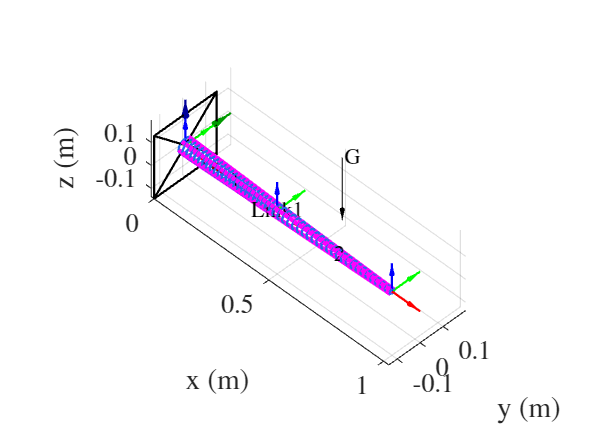

S1.plotq0

The result should be:

The beam is rigidly fixed at one end and can be subjected to actuation forces (6 oblique actuators).

### **Static equilibirum analysis**

For statics equilibirum analysis type:

Solving Static Equilibrium

                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          1         6.60998e+15                        5.47e+16              1
     1          2         1.17464e+15              1         1.26e+16              1
     2          3         2.11812e+14            2.5         7.31e+15            2.5
     3          4         6.27134e+12           6.25         4.27e+14           6.25
     4          5         3.86173e+06        1.86907         2.49e+11           15.6
     5          6          0.00110753    0.000147039         7.71e+06           15.6
     6          7         2.05115e-16    4.06068e-08             11.7           15.6
     7          8         2.87651e-19    6.45953e-15            0.135           15.6

Equation solved, solver stalled.

fsolve 

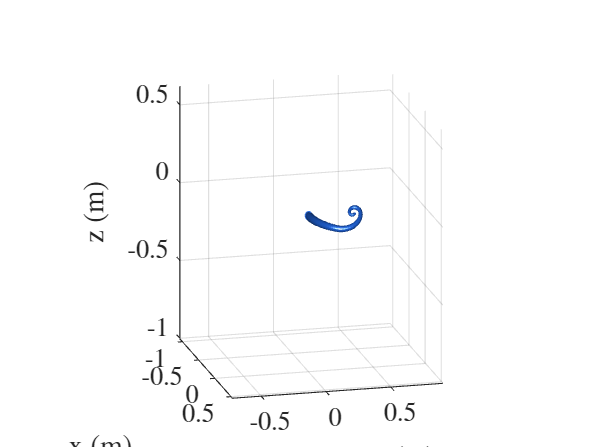

q=S1.statics;

You will be prompted to enter the actuation force in the command window. Enter the input actuation forces into cables 1 and 2 respectively. eg: -50, -35, -10, -20, -40, -10.

A dialog box will then pop up, asking for the initial guess. The user can choose the default value.

The equilibirum solution is,

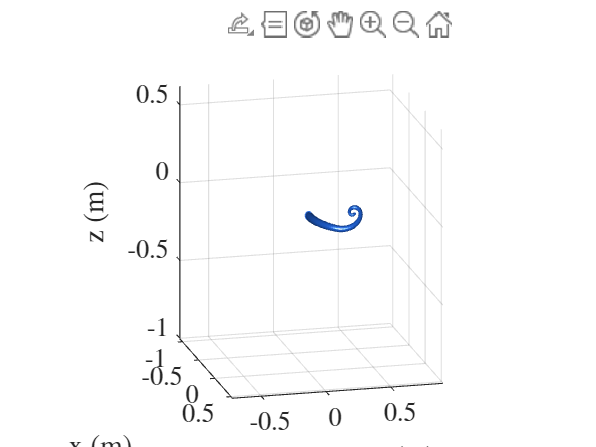

Alternatively you can run:

Solving Static Equilibrium

                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          1          4.7237e+15                        4.48e+16              1
     1          2         9.54365e+14              1         1.13e+16              1
     2          3         2.00879e+14            2.5         7.05e+15            2.5
     3          4          1.6799e+13           6.25         7.63e+14           6.25
     4          5         1.62244e+08        3.97942         1.42e+12           15.6
     5          6             3.18422    0.000713751         4.13e+08           15.6
     6          7         6.01219e-16    3.08202e-06             5.91           15.6
     7          8         9.65723e-19    4.07435e-15            0.128           15.6

Equation solved, solver stalled.

fsolve 

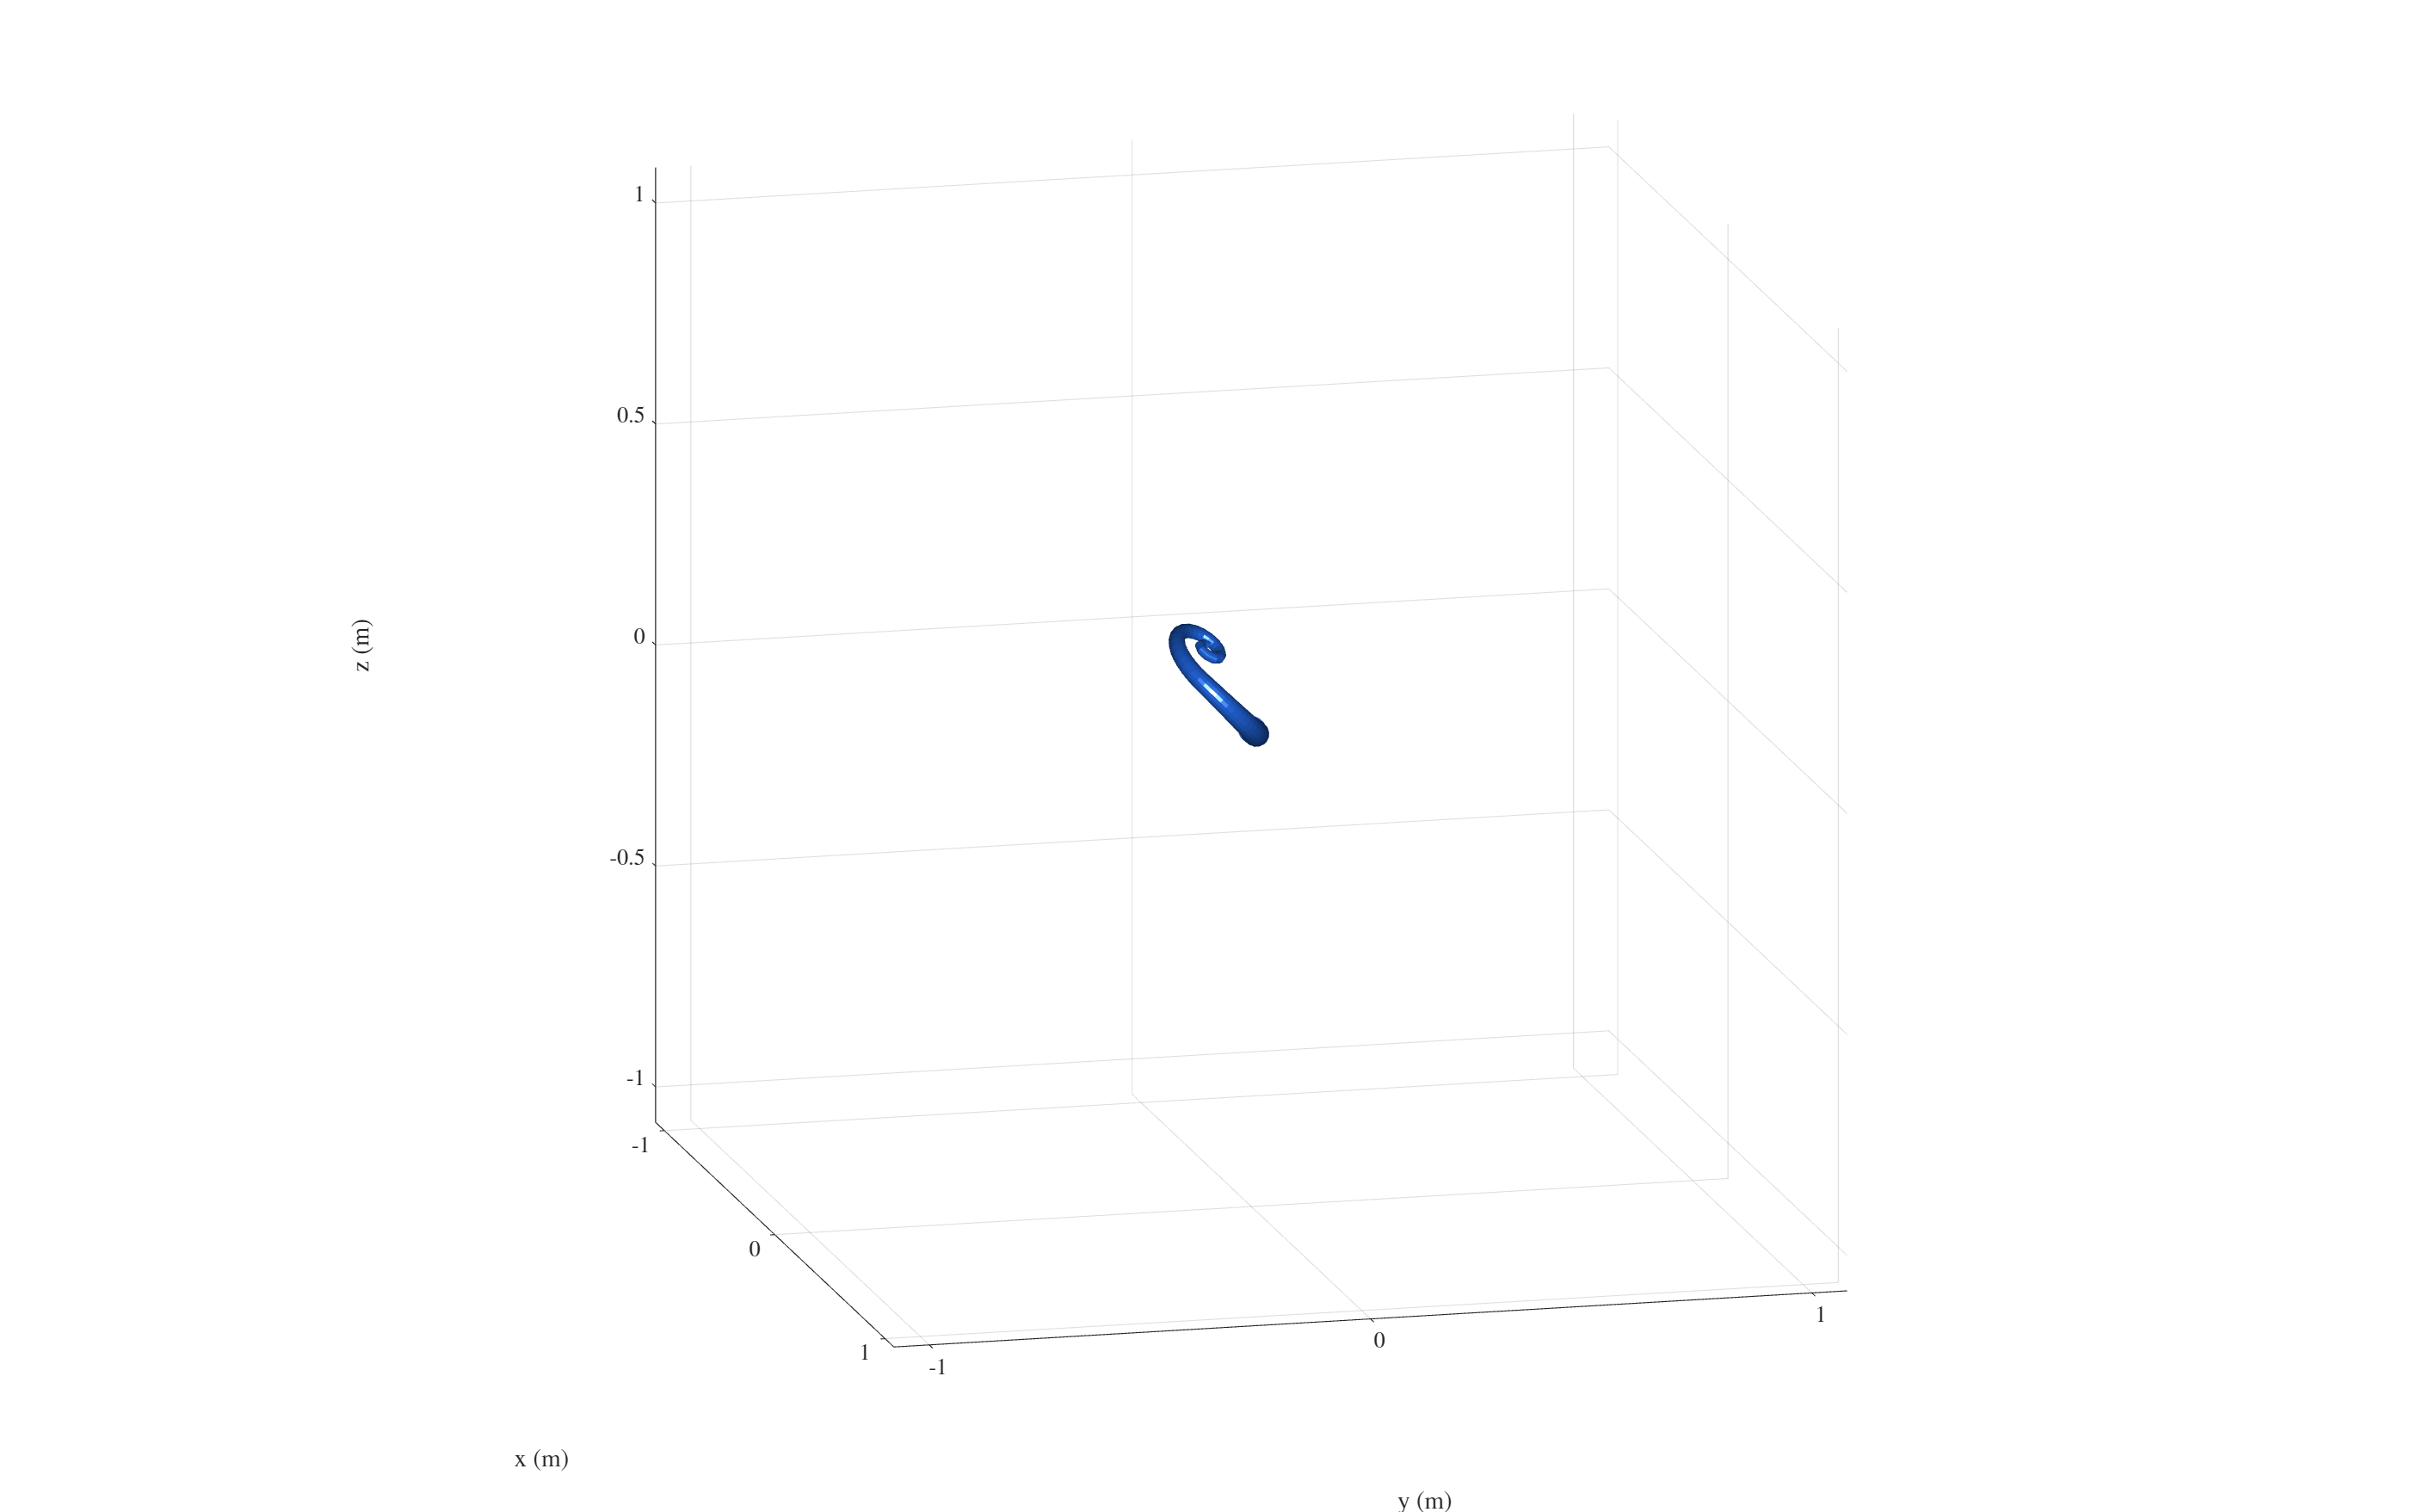

q = S1.statics([],[-20, -55, -10, -40, 0, -10]');

### **Dynamics**

For dynamics problem, type:

[t,qqd]=S1.dynamics([],@dynamicActionInputSM);

Modify the function dynamicActionInputSM.m to update the actuation input. If the function is not specified, the input can be given from the command window.

Initial conditions of state coordinates ($$\mathbf{q_0}$$) and their derivatives ($$\mathbf{\dot{q_0}}$$) will then be asked in a dialog box. The user can also choose the time for which the simulation is run (the default value is 5 s).

The results of the dynamic simulation (`t` and `qqd`) will be saved in `DynamicsSolution.mat `in the folder from which the simulation is run.

At the end of simulation, in the dialog box that appear, choose to generate the video if needed.  This step will take some time. 

A video named `Dynamics.mp4` will be saved in the folder.

Enable gravity and try again.

S1.Gravity=true;